# Unit 4.3: Fourier Transforms for Circuit and LTI Analysis

Prepared for EG-247 Digital Signal Processing by Dr C.P. Jobling

## Example 4

Karris example 8.11: the voltage across a 1$\Omega$ resistor is known to be $V_{R}(t)=3e^{-2t} u_0(t)$. Compute the energy dissipated in the resistor for $0\lt t\lt\infty$, and verify the result using Parseval's theorem. Verify the result with MATLAB.

Note from [tables of integrals](https://en.wikipedia.org/wiki/Lists_of_integrals)


$$$$\int\frac{1}{a^2 + x^2}\,dx = \frac{1}{a}\arctan\frac{x}{a}+C.$$$$


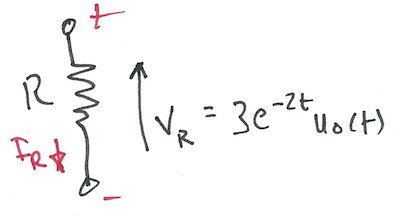

Worked solution: [ft3-ex4.pdf](https://cpjobling.github.io/eg-247-textbook/fourier_transform/solutions/ft3-ex4.pdf).

### Set Up

syms t w

### Calcuate energy from time function

Vr = 3*exp(-2*t)*heaviside(t);
R = 1;
Pr = Vr^2/R
Wr = int(Pr,t,0,inf)
double(Wr)

### Calculate energy using Parseval's theorem

Fw = fourier(Vr,t,w)

Fw2 = simplify(abs(Fw)^2)

Wr=2/(2*pi)*int(Fw2,w,0,inf)
double(Wr)